# Simulated Experiment

David Olson, 28 Apr 2021

## Generate Planes

% Plane Test Widths
dist = 0.5 : 0.1 : 5;
a = 57 * pi/180;
b = 43 * pi/180;

% Constant Plane Parameters
psi   = 0 * 180/pi;
theta = pi/2;
C = rotate_z(psi) * rotate_y(theta);
sigmas = 0 * [1; 1; 1];

% Pre-Allocate for Cell Array
xyz = cell(length(dist), 1);

% Varying Plane Parameters
for ii = 1 : length(dist)
   
    n = 100;
    org = [dist(ii), 0, 0];
    dim = [-dist(ii) * tan(a/2),  dist(ii) * tan(a/2); ...   % x params
           -dist(ii) * tan(b/2),  dist(ii) * tan(b/2)];      % y params
   
    % Generate Point Cloud using the Same Parameters
    xyz{ii} = gen_plane(C, org, dim, n, sigmas);
    
end


## Plot all Test Points on one plot

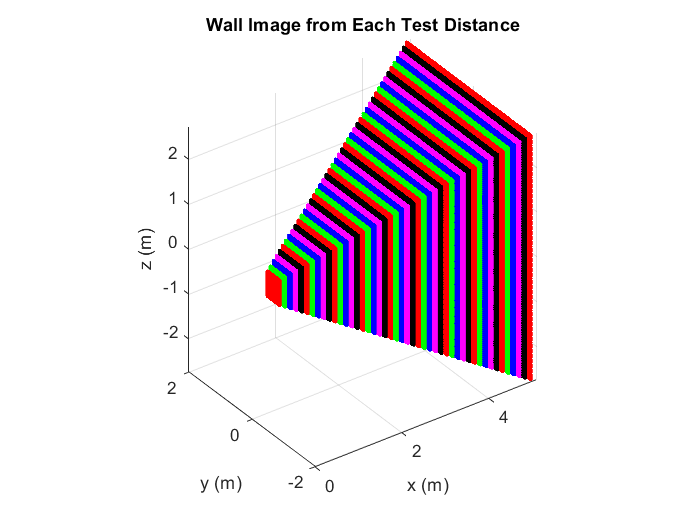

clr_str = ['k', 'r', 'g', 'b', 'm'];

% Plot Data
figure
hold on
for ii = 1 : length(xyz)
    plot3(xyz{ii}(1,:), xyz{ii}(2,:), xyz{ii}(3,:), [clr_str(mod(ii,5)+1), '.']);
end
title('Wall Image from Each Test Distance')
xlabel('x (m)') 
ylabel('y (m)')
zlabel('z (m)')
axis equal
xlim([0, max(dist) + 0.1])
% xticks(0:0.1:3)
view([-35.952 33.083])
grid
hold on

## Run SNHT Experiment

Run #1 of 46 


Elapsed time is 10.193817 seconds.


Run #2 of 46 


Elapsed time is 10.777484 seconds.


Run #3 of 46 


Elapsed time is 11.233180 seconds.


Run #4 of 46 


Elapsed time is 11.996678 seconds.


Run #5 of 46 


Elapsed time is 17.843895 seconds.


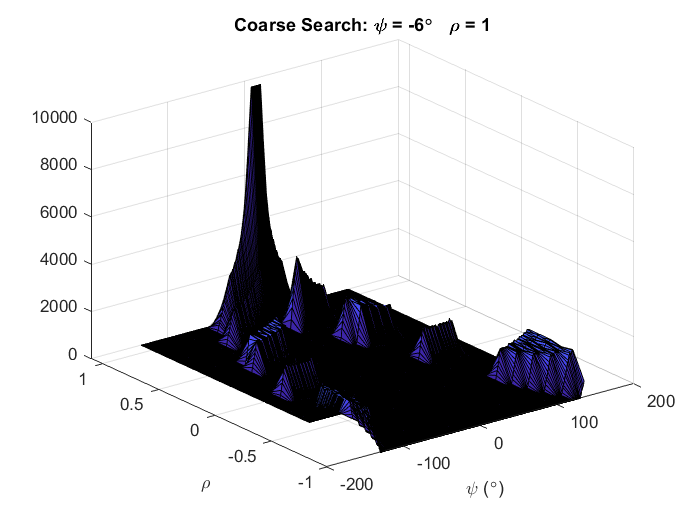

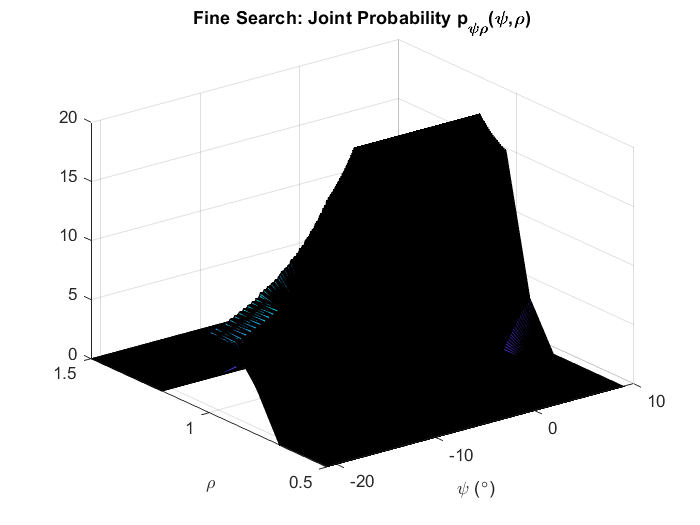

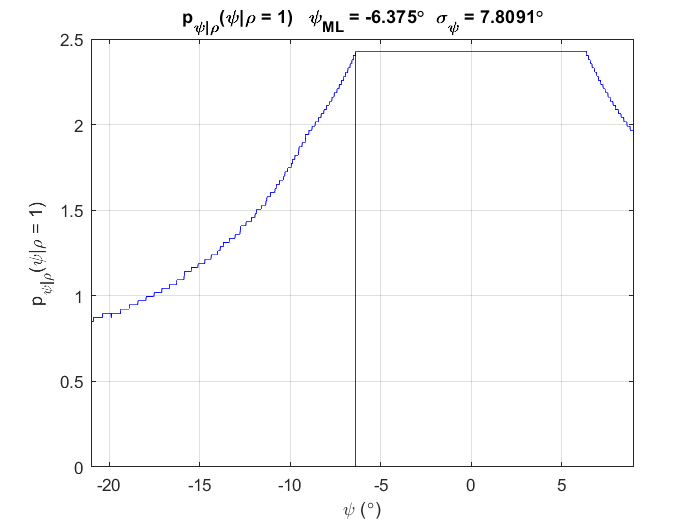

Run #6 of 46 


Elapsed time is 10.550803 seconds.


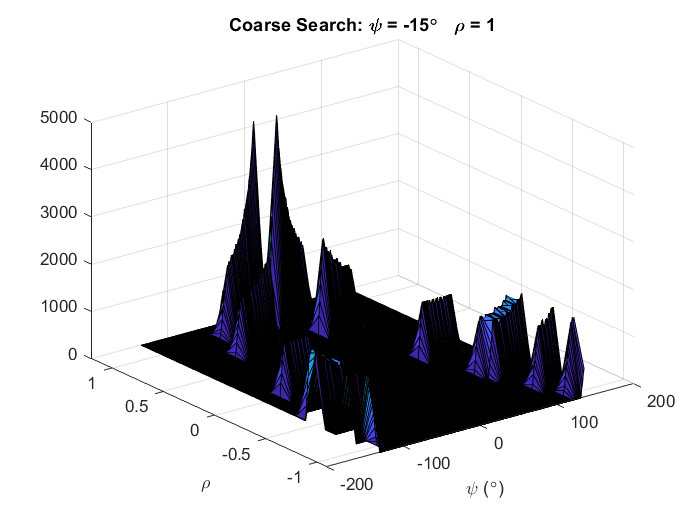

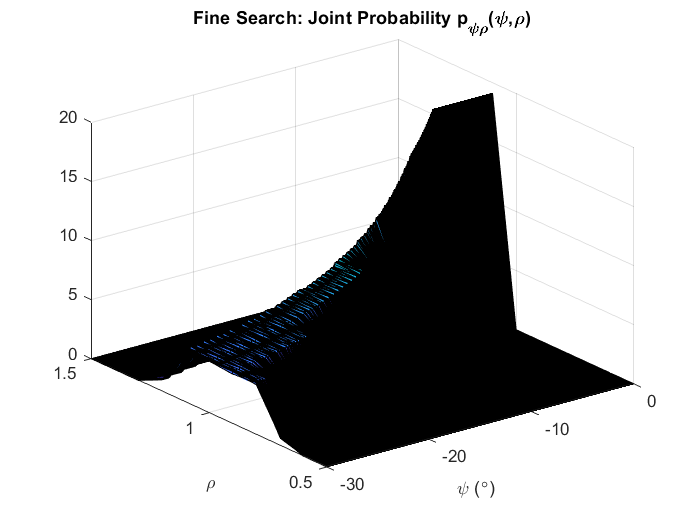

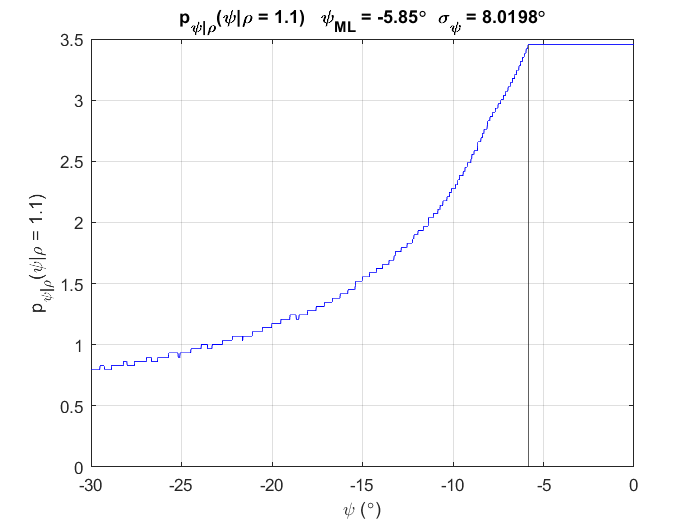

Run #7 of 46 


Elapsed time is 10.894691 seconds.


Run #8 of 46 


Elapsed time is 11.236531 seconds.


Run #9 of 46 


Elapsed time is 16.038892 seconds.


Run #10 of 46 


Elapsed time is 12.506922 seconds.


Run #11 of 46 


Elapsed time is 10.260590 seconds.


Run #12 of 46 


Elapsed time is 10.572062 seconds.


Run #13 of 46 


Elapsed time is 17.241803 seconds.


Run #14 of 46 


Elapsed time is 18.872703 seconds.


Run #15 of 46 


Elapsed time is 12.754940 seconds.


Run #16 of 46 


Elapsed time is 10.291072 seconds.


Run #17 of 46 


Elapsed time is 17.150370 seconds.


Run #18 of 46 


Elapsed time is 11.107218 seconds.


Run #19 of 46 


Elapsed time is 14.038620 seconds.


Run #20 of 46 


Elapsed time is 10.615710 seconds.


Run #21 of 46 


Elapsed time is 10.427282 seconds.


Run #22 of 46 


Elapsed time is 10.754387 seconds.


Run #23 of 46 


Elapsed time is 17.001279 seconds.


Run #24 of 46 


Elapsed time is 13.804445 seconds.


Run #25 of 46 


Elapsed time is 10.654836 seconds.


Run #26 of 46 


Elapsed time is 10.397187 seconds.


Run #27 of 46 


Elapsed time is 10.645309 seconds.


Run #28 of 46 


Elapsed time is 16.978583 seconds.


Run #29 of 46 


Elapsed time is 13.729373 seconds.


Run #30 of 46 


Elapsed time is 11.403871 seconds.


Run #31 of 46 


Elapsed time is 10.979183 seconds.


Run #32 of 46 


Elapsed time is 10.790311 seconds.


Run #33 of 46 


Elapsed time is 13.312730 seconds.


Run #34 of 46 


Elapsed time is 14.013970 seconds.


Run #35 of 46 


Elapsed time is 11.935979 seconds.


Run #36 of 46 


Elapsed time is 10.865321 seconds.


Run #37 of 46 


Elapsed time is 11.005684 seconds.


Run #38 of 46 


Elapsed time is 13.743277 seconds.


Run #39 of 46 


Elapsed time is 12.824295 seconds.


Run #40 of 46 


Elapsed time is 14.196604 seconds.


Run #41 of 46 


Elapsed time is 11.195127 seconds.


Run #42 of 46 


Elapsed time is 10.945922 seconds.


Run #43 of 46 


Elapsed time is 16.489303 seconds.


Run #44 of 46 


Elapsed time is 12.812577 seconds.


Run #45 of 46 


Elapsed time is 14.803136 seconds.


Run #46 of 46 


Elapsed time is 11.065841 seconds.


% SNHT Wall Parameters
psi_params = [-45, 0.05, 45] * pi/180;
plot_flag = false;

% Run the SNHT on each wall image
mode_psi = zeros(1, length(xyz));
psi_var = zeros(1, length(xyz));

for k = 1 : length(xyz)
    
    % start timer
    tic
    
    if ((k == 6) || (k == 7))
        plot_flag = true;
    else 
        plot_flag = false;
    end
    
    [mode_psi(k), psi_var(k)] = SNHT_wall_2stage_search(xyz{k}, plot_flag);
    
    % end timer
    fprintf('Run #%d of %d \n', k, length(dist))
    toc
    
end

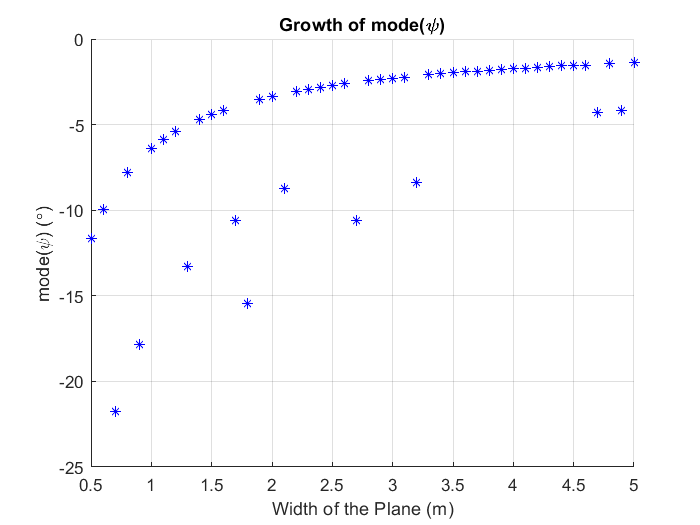


% Plot Results
figure
hold on
plot(dist, mode_psi * 180/pi, 'b*')
title('Growth of mode(\psi)')
xlabel('Width of the Plane (m)')
ylabel('mode(\psi) (\circ)')
grid on 
hold off

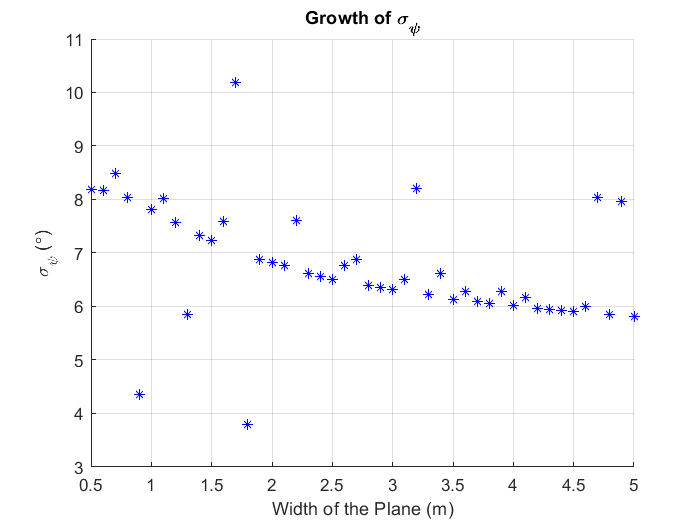


% Plot Results
figure
hold on
plot(dist, sqrt(psi_var) * 180/pi, 'b*')
title('Growth of \sigma_\psi')
xlabel('Width of the Plane (m)')
ylabel('\sigma_\psi (\circ)')
grid on 
hold off